# single qubit dynamics:

## one-qubit with drive Hamiltonian:


H0=qeye(2);
sm = sigmam();
rotd = sigmaz();

gamma = 1/35e3;
gammap = (1/25e3 - 1/(2*35e3))/2;
n_th_q = 0.01;
cops = {};
rate = gamma*(1+n_th_q);
if rate>0
    cops{end+1}=sqrt(rate)*sm;
end
rate = gamma*n_th_q;
if rate>0
    cops{end+1}=sqrt(rate)*sm';
end
rate = gammap;
if rate>0
    cops{end+1}=sqrt(rate)*rotd;
end

mysigma=10;
tlist = linspace(0,4*mysigma,4*mysigma+1);

theta=2*pi; phi0=0;  % ===> R_phi (theta)
A = integral(@(x) exp(-(x/mysigma).^2/2),-2*mysigma,2*mysigma);
Ht_coeff1 = @(t) (theta)/A*exp(-((t-2*mysigma)/mysigma).^2/2)*exp(1i*phi0);
Ht_coeff2 = @(t) (theta)/A*exp(-((t-2*mysigma)/mysigma).^2/2)*exp(-1i*phi0);
Ht1 = 0.5*sigmap();
Ht2 = 0.5*sigmam();
tH_list = {Ht_coeff1, Ht_coeff2;
           Ht1,       Ht2};

psi0 = unit(1*basis(0)-0*basis(1));
psi1_ideal = state2dm(unit(rotation(theta,sigmax()*cos(phi0)+sigmay()*sin(phi0))*psi0))

psi1_ideal =    1.0000 + 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i


% psi0 = state2dm(psi0);

results = mesolve(H0,tH_list,tlist,psi0,{},{});
psi1 = unit(results.state{end})

psi1 =    1.0000 - 0.0000i
  -0.0000 - 0.0000i


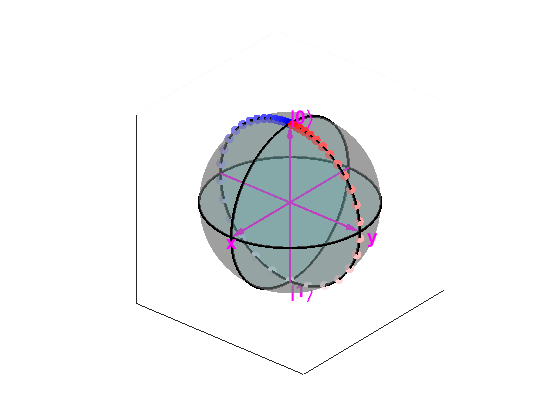

bloch();
bloch_addstates(results.state);

fidelity = cal_fidelity(psi1,psi1_ideal)

fidelity = 1.0000


% results = sesolve(H0,tH_list,tlist,psi0,{});
% psi1 = unit(results.state{end})
% 
% fidelity = cal_fidelity(psi1,psi1_ideal)
% bloch();
% bloch_addstates(results.state);